## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
path = '~/Documents/Courses/ELEC-E5620 Audio Signal Processing/Demo_FVN';
addpath([path '/matlab/functions']);

## Load soundfile

addpath([path '/snd']);
[X, Fs] = audioread('pori.wav');

## Define input

% test signal: impulse
sig = [1; zeros(49, 1)];

# Prepare for auto-segmentation

#### Divide IR into segments to analyze

starttime = 0.1;    % start time (seconds)
winsize = 2048;     % analysis window size
hopsize = 500;      % analysis window hop

start = floor(starttime * Fs);
nwin = floor(((length(X) - start) - (winsize-hopsize)) / (hopsize+1));
segments = zeros(winsize, nwin);

% collect the "sliding window" of samples
winStSamps = zeros(nwin, 1);
for i = 1:nwin
    st = start + (hopsize * (i-1));
    winStSamps(i) = st;
    segments(:, i) = getSamples(X, st, winsize);
end

clear st start

# Linear Prediction: spectral estimate on matrix

lpcOrder = 10;           % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(segments, lpcOrder, frq_resolution, Fs);

### Analyse the frequency rolloff 

rolloff_db = -20;
search_above = 750;

[rollidxs, rollfreqs, rollvals] = rolloffIdx( ...
    mags_norm, rolloff_db, search_above, Fs);

clear rolloff_db search_above

# Find segment boundaries

frqHigh = rollfreqs(1);
frqLow  = 260;      % found through inspection
segthresh = 0.04;   % percentage of frqHigh to advance between segments
freqstep = frqHigh * segthresh;

segStartIdxs = [winStSamps(1)];
cnt = 1; % analysis window counter
nextBoundaryFrq = frqHigh - freqstep;

while (nextBoundaryFrq >= frqLow) && (cnt <= length(rollidxs))
    thisfrq = rollfreqs(cnt);
    if (thisfrq < nextBoundaryFrq)
        % add this window's start frame to the segment boundary list
        segStartIdxs = [segStartIdxs winStSamps(cnt)];
        nextBoundaryFrq = nextBoundaryFrq - freqstep;
    end
    cnt = cnt+1;
end

if cnt == length(rollidxs)
    warning("reached the end of the analysis window list")
end
if nextBoundaryFrq < frqLow
    disp("*** next boundary fell below frqLow ***")
end

#### plot segment divisions

segBoundaries = [segStartIdxs length(X)]; % add the endpoint in for plotting
nBoundaries = length(segBoundaries);
stairs(segBoundaries, nBoundaries:-1:1);
yticks([1 nBoundaries])
xticks(round(segStartIdxs(1), -4):10000:round(length(X),-4))
yticklabels(["last" "first"]);
ylabel('segment index')
xlabel('sample index')
ylim([0,nBoundaries+1])
title({"Segment Boundaries", ...
    sprintf("Number of segments: %d", length(segStartIdxs))})

clear nBoundaries segBoundaries

# Analysis: Whiten IR Segments

### Retrieve segments

seg_bounds = [segStartIdxs'; length(X)];
M = seg_bounds(2:end) - seg_bounds(1:end-1);
nSeg = length(M);

% IR segments
segments = {};

for i = 1:nSeg
    st = seg_bounds(i);
    len = M(i);
    %     segments{i} = X(st:st+len-1);
    segments{i} = getSamples(X, st, len);
end

seg_nsamp = seg_bounds(2:end) - seg_bounds(1:end-1);
% seg_nsamp(end) = seg_nsamp(end) + 1;

clear i M n

#### plot segments

plot_idxs = 1:2:nSeg;
cnt = 1;
for i = plot_idxs
    subplot(length(plot_idxs), 1, cnt)
    plot(segments{i})
    cnt = cnt+1;
end

figure();
% include initial silence where the first/early arrivals are
end_idx = seg_bounds(1)-1;
plot((1:end_idx) ./ Fs, zeros(end_idx, 1)); % inital (unsynthesized) part of response
hold on;
for i = 1:nSeg
    st_idx = seg_bounds(i); % seg_bounds is size nSeg+1
    end_idx = st_idx + seg_nsamp(i) - 1;
    plot((st_idx:end_idx) ./ Fs, segments{i});
end
for i = 1:nSeg
    st_idx = seg_bounds(i);
    xline(st_idx / Fs, "--");
end
hold off;

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nSeg+1);
colororder([rgb; rgb]);
ylabel('amplitude');
xlabel('time (s)')
clear plot_idxs cnt

## Generate LPC whitening filters

lpc_order = 10;
whiten = true;
mag_resolution = 2048; % for plotting

% storage
mags_lpc = zeros(mag_resolution, nSeg);
freqs_lpc = zeros(mag_resolution, nSeg);
coeffs_lpc = zeros(lpc_order+1, nSeg);

for i = 1:nSeg
    [mags, ~, freqs, coeffs] = lpcData( ...
        segments{i}, lpc_order, mag_resolution, Fs, whiten);
    mags_lpc(:,i) = mags; % just keep the normalized spectrum for plotting
    freqs_lpc(:,i) = freqs;
    coeffs_lpc(:, i) = coeffs;
end

clear mags mags_norm freqs coeffs i

#### Plot whitening filter magnitudes

% plt = semilogx(freqs_lpc, mags_lpc);
plt = plot(freqs_lpc, mags_lpc);
% disp(plt(:).LineWidth)
set(plt,'LineWidth',1.5)
axis tight;
colororder(rgb);
xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Magnitude response of whitening filters, LP order: %d", lpc_order))

## Whiten the segments, measure their power

% "whiten" the original segments
segments_white = {};
for i = 1:nSeg
    segments_white{i} = filter(coeffs_lpc(:, i), [1], segments{i});
end

% recompute spectrum estimate ... is it flat?
% storage
mags_lpc_whitened = zeros(mag_resolution, nSeg);
freqs_lpc_whitened = zeros(mag_resolution, nSeg);
whiten = false;

for i = 1:nSeg
    [mags, ~, freqs, ~] = lpcData( ...
        segments_white{i}, lpc_order, mag_resolution, Fs, whiten);
    mags_lpc_whitened(:,i) = mags; % just keep the normalized spectrum
    freqs_lpc_whitened(:,i) = freqs;
end

#### Plot LP magnitudes of whitened segments

% plt = semilogx(freqs_lpc_whitened, mags_lpc_whitened);
plt = plot(freqs_lpc_whitened, mags_lpc_whitened);
set(plt,'LineWidth',1.5)
axis tight;
colororder(rgb);
xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Spectral estimates of whitened segments, LP order: %d", lpc_order))

% clear freqs_lpc_whitened mags_lpc_whitened ...
%     mags mags_norm freqs coeffs

## Analyze signal power of whitened segments

power_whitened = zeros(nSeg, 1);
for i = 1:nSeg
    power_whitened(i) = mean(segments_white{i}.^2); % TODO as;ldkf
%     power_whitened(i) = mean(segments{i}.^2);
end

reference_gains = mag2db(power_whitened);
% normalized to 0dB
reference_gains_norm = reference_gains - max(reference_gains);

### Plot Power of reference segments

plot(reference_gains_norm); hold on;

for i = 1:length(reference_gains_norm)
    plot(i,reference_gains_norm(i), 'o', ...
        'MarkerFaceColor', rgb(i, :), 'MarkerSize', 10);
end
hold off;

title("Signal power of whitened IR segments.")
xlabel("segment index");
ylabel("magnitude (dB)");

# Velvet Noise Sequences

"*N*d = 100 pulses/s is sufficient in the very beginning of the late reverberation, where segments are very short, whereas *N*d = 40 pulses/s can be enough at the end where the bandwidth gets narrow. Between these extremes, the density is decreased linearly as a function of the segment index *m*." p. 7

#### Generate long sequences for gain matching

analysis_dur = round(1 * Fs); % duration of segments for gain analysis

max_pfreq = 200; % max pulse freq
min_pfreq = 60;  % min pulse freq

vn_pfreqs = linspace(max_pfreq, min_pfreq, nSeg);

% matrix for long sequence
vn_seq_long = zeros(analysis_dur, nSeg);
% cell array for sequences to be used in the synthetic IR
vn_seq = {};
stretch = 10;

for i = 1:nSeg
    vn_seq_long(:, i) = velvet(analysis_dur, vn_pfreqs(i), Fs);
    if seg_nsamp(i) < Fs/vn_pfreqs(i) % if segment length is shorter than pulse period
        % make sure a pulse falls within the segment
        vn_seq{i} = velvet(seg_nsamp(i)*stretch, vn_pfreqs(i), Fs, true);
    else
        vn_seq{i} = velvet(seg_nsamp(i)*stretch, vn_pfreqs(i), Fs);
    end
end

clear min_pfreq max_pfreq vn_pfreqs

#### Plot some of the sequences

% plot long analysis segments (1), or IR modeling segments (0)
plotLongSegs = false;
plt_idx = 1:2:nSeg;

longest_seg = length(vn_seq{plt_idx(end)});

for i = 1:length(plt_idx)
    subplot(length(plt_idx), 1, i);
    if plotLongSegs
        plot(vn_seq_long(:, plt_idx(i))); hold on;
    else
        plot(vn_seq{plt_idx(i)}); hold on;
    end
    xlim([1 longest_seg]);
end
hold off

clear plt_idx plotLongSegs

# Coloration Filters

#### Generate the differential notch filters

H1A = coeffs_lpc(:,1);
H1B = [1; zeros(lpc_order, 1)];
fc_range = [16000 8000]; % notch center freq range (first > last seg)
fb_range = [5000 4000];  % notch bw range (first > last seg)
G_range  = [-6 -4];      % notch filter gain range
Hs = false;               % if true, add high shelf
Hs_fc = 20000;           % center freq of high shelf (center of skirt)
Hs_g = -100;             % gain of high shelf

[Adiff, Bdiff, Acolor, Bcolor] = GenDiffFilters( ...
    H1A, H1B, nSeg, fc_range, fb_range, G_range ,Fs, Hs,Hs_fc, Hs_g);

#### Plot differential filters

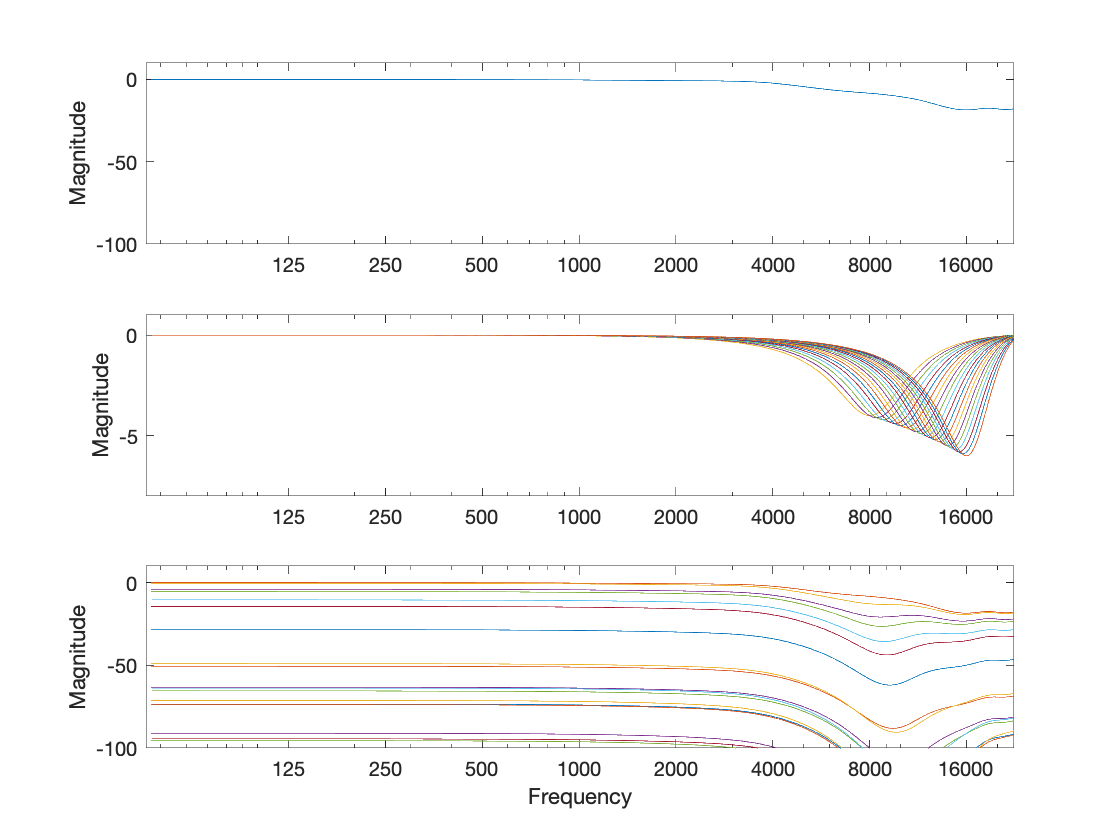

% plt_gains
filterplot(Bcolor, Acolor, Bdiff, Adiff, Fs, makeup_gains - max(makeup_gains));

## Filter ("colorize") the long VN sequences

vn_seq_colored = zeros(analysis_dur, nSeg);

for i = 1:nSeg
    vn_seq_colored(:,i) = filter(Bcolor{i}, Acolor{i}, vn_seq_long(:,i));
end

## Whiten the colorized VN sequences (experimental)

for i = 1:nSeg
    vn_seq_colored_white{i} = filter( ...
        coeffs_lpc(:, i), [1], vn_seq_colored(:,i));
end

## All-pass cascade: send colorized VN sequences through for analysis

a_AP = 0.7;                     % all-pass coefficient
d_AP = [ 225, 341, 441, 556 ];  % all-pass delays

% process just one to get the appropriate returned
vn_seq_colored_ap = zeros(analysis_dur, nSeg);
vn_seq_colored_whtie_ap = zeros(analysis_dur, nSeg);

for i = 1:nSeg
    % note: rolloff_threshold is omitted, so returned signal is same size
    % as X. analysis should be done after the "warmup" period of the
    % response.
%     vn_seq_colored_ap(:,i) = apCascade(vn_seq_colored(:,i), a_AP, d_AP);
%     % TODO a;ldkfasdja;oivja;ivm;alsrijdg;ladf
    vn_seq_colored_white_ap(:,i) = apCascade(vn_seq_colored_white{i}, a_AP, d_AP);
end

#### Plot spectrum of the colored VN

idx = 11;
% plot(mag2db(abs(fft(vn_seq_colored(:,idx)))))
% xlim([1 ceil(length(vn_seq_colored(:,idx))/2)])
plot(mag2db(abs(fft(vn_seq_colored_ap(:,idx)))))
xlim([1 ceil(length(vn_seq_colored_ap(:,idx))/2)])

% plot(mag2db(abs(fft(vn_sequences(:,1)))))
ylim([-40 40])

clear idx

#### Plot filter responses of notch filters

sz = 2048;
Hs = zeros(sz, nSeg-1);
for i = 1:nSeg-1
    [H, w] = freqz(Bdiff(:,i), Adiff(:,i), sz);
    Hs(:,i) = H;
end
plot(w./pi*Fs/2, mag2db(abs(Hs)))
clear sz i

## Calculate the power of the colored, all-passed VN

power_vn = zeros(nSeg, 1);
for i = 1:nSeg
%     power_vn(i) = mean(vn_seq_colored(:,i).^2);
%     power_vn(i) = mean(vn_seq_colored_ap(:,i).^2);
    power_vn(i) = mean(vn_seq_colored_white_ap(:,i).^2);
end

vn_seq_gains = mag2db(power_vn);
% normalized to 0dB
vn_seq_gains_norm = vn_seq_gains - max(vn_seq_gains);

#### Plot Power of reference segments

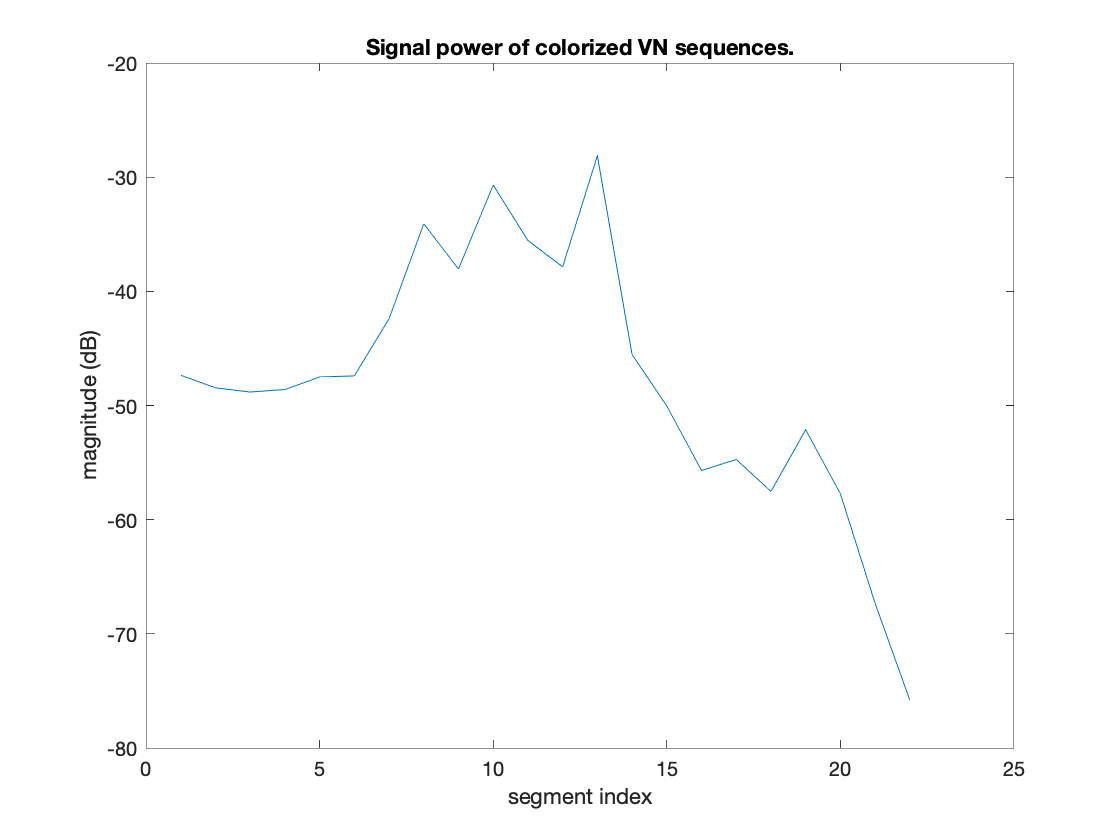

plot(vn_seq_gains)
title("Signal power of colorized VN sequences.")
xlabel("segment index");
ylabel("magnitude (dB)");

#### Plot Power of reference segments with analyzed IR segment power

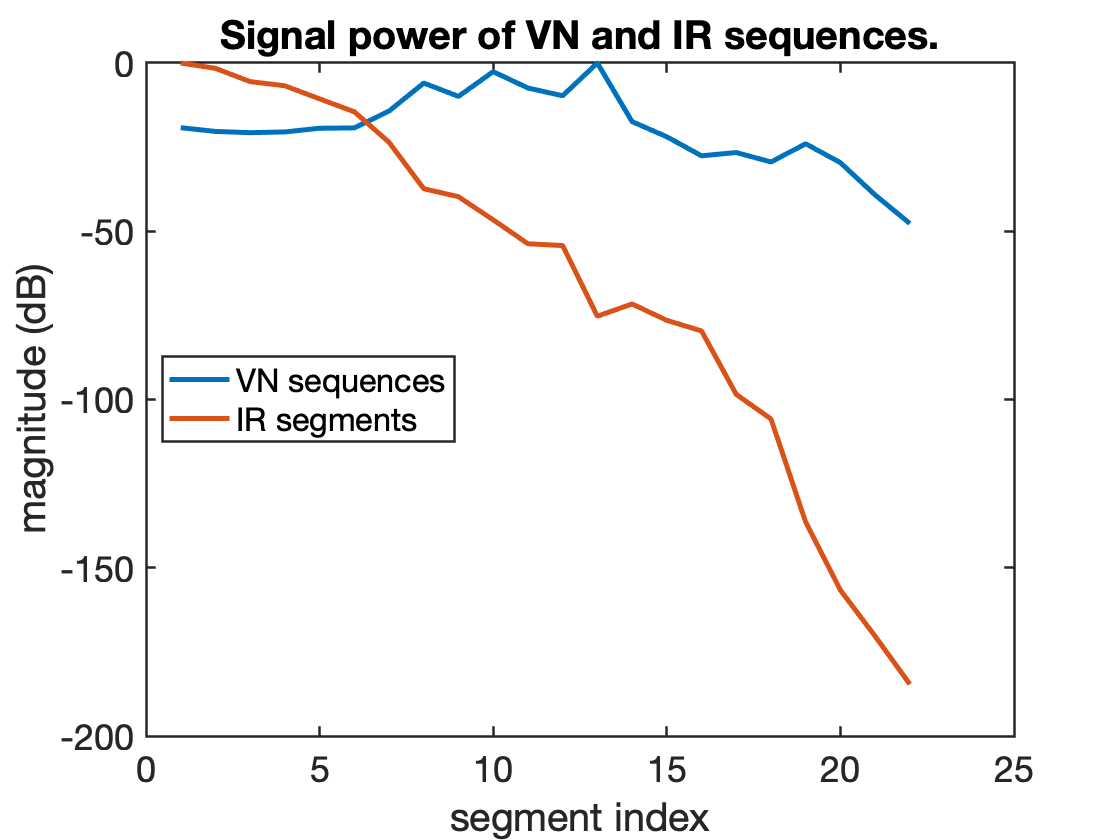

plot([vn_seq_gains_norm reference_gains_norm], 'LineWidth', 2.5);
% plot([vn_seq_gains reference_gains], 'LineWidth', 2.5);

title("Signal power of VN and IR sequences.")
xlabel("segment index");
ylabel("magnitude (dB)");
legend(["VN sequences" "IR segments"], "Location", "west")
set(gca, 'FontSize', 18)
set(gca, 'LineWidth', 1.25)

## Calculate the makeup gain

makeup_gains = reference_gains_norm - vn_seq_gains;

## Generate optional logarithmic decay curve

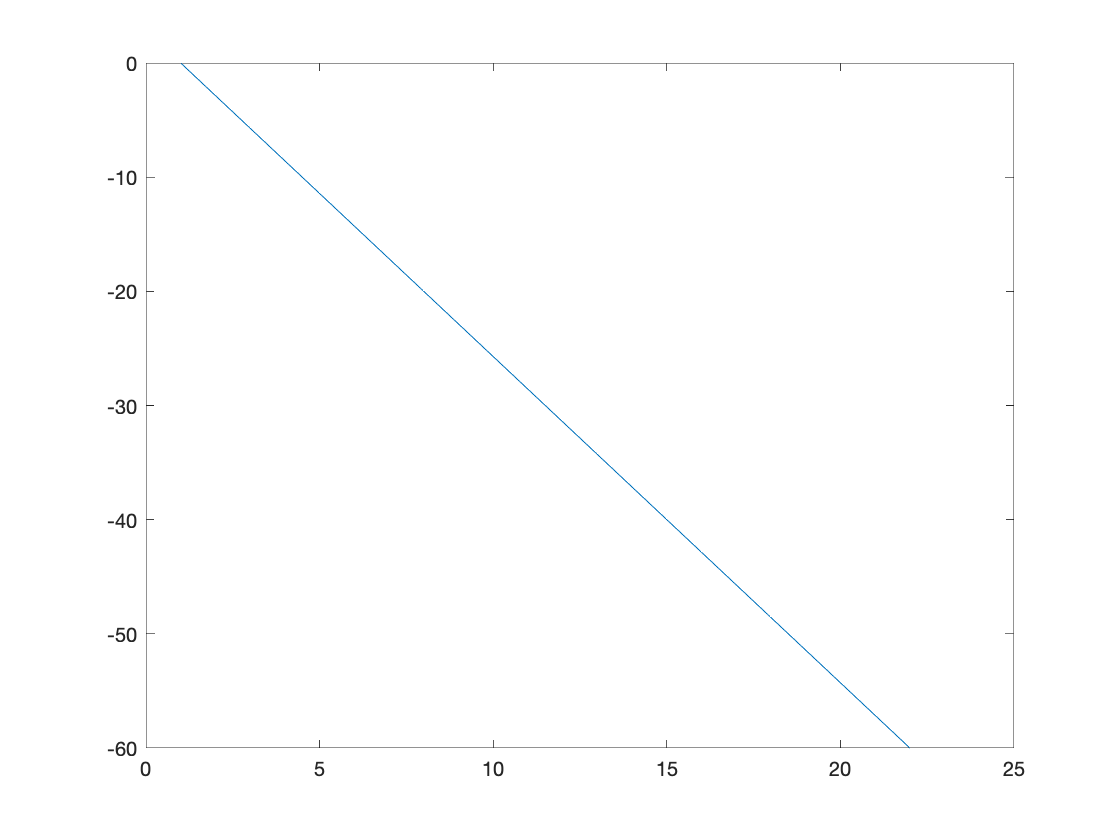

stdb = 0;
enddb = -60;
n = nSeg;

log_decay = exp(linspace(log(db2mag(stdb)), log(db2mag(enddb)), n));

% plot(log_decay-60)
% semilogy(log_decay)
plot(mag2db(log_decay))


clear stdb enddb n

# Putting it all together

A tap is taken after each coloration+VNC stage.

#### Choose input signal

input = [1; zeros(2047, 1)];

#### **Calculate the output buffer size**

The buffer size of each stage is **size(input) + size(convKernel) - 1**

outsize = length(input) + sum(seg_nsamp) - nSeg;
outsize = outsize*2; % TODOLKSDF:LKJDFL:KSDJFKLSDJF:SDJF:SDJF:SDFJS:D

#### Pack filter coeffs into 1 structure

colorFiltA{1} = H1A;
colorFiltB{1} = H1B;
for i = 1:nSeg-1
    colorFiltA{i+1} = Adiff(:,i);
    colorFiltB{i+1} = Bdiff(:,i);
end

#### Generate output taps after each filter+VNC

% output matrix holding network taps, pre-gain, pre-SAP
taps = zeros(outsize, nSeg);
prevseqlen = 0;

% loop through the cascade, segment by segment
for i = 1:nSeg
    % ~~~ filter input with coloration filter ~~~
    filtered = filter(colorFiltB{i}, colorFiltA{i}, input);
    
    % ~~~ convolve with VN sequence ~~~
%     convolved = conv(filtered, vn_seq{i});
    
    convseq = [zeros(prevseqlen,1); vn_seq{i}];
    convolved = conv(filtered, convseq);
    
    % ~~~ zero-pad each output tap to fit in the tap matrix ~~~
    padlen = outsize-length(convolved);
    padded = [convolved; zeros(padlen,1)];
    
    % ~~~ apply gain term ~~~
    padded = padded * db2mag(makeup_gains(i)/2); % TODOOOOOOO:LK:LDKNV:SDVN:DV
    
    % store output
    taps(:, i) = padded;
    
    % rotate variables for next iteration
%     input = convolved;
    input = filtered;
    prevseqlen = prevseqlen+length(vn_seq{i});
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.


summed_ir = sum(taps, 2);

clear padded convolved prevseqlen input

#### Plot the post-gain IR

plotsig = summed_ir;
plotsig = abs(plotsig);
plot(plotsig, 'LineWidth', 1); legend();
% semilogy(plotsig, 'LineWidth', 1); legend();
% xlim([1 14400])
clear plotsig

#### Plot each tap stage

plotsig = taps(:,end:-1:1); % reverse
plotsig = abs(plotsig);
plot(plotsig, 'LineWidth', 1); legend();
% semilogy(plotsig, 'LineWidth', 1); legend();
% xlim([1 14400])

rgb = genColors(0.3, 0.1, nSeg);
colororder(rgb);

clear plotsig

#### View FFT of a tap

idx =12;
plotOneFFT(taps(:,idx), 4096, Fs)
clear idx

#### Plot one tap

idx = 2;
plotsig = taps(:,idx);
plotsig = abs(plotsig);
plot(plotsig, 'LineWidth', 1); legend();
clear plotsig idx

#### Listen to the post-gain (pre-all-pass) IR

idx = 15;
norm = taps(:,idx)/max(taps(:,idx));
soundsc(norm, Fs)
clear norm idx

#### Listen to the post-gain (pre-all-pass) IR

norm = summed_ir/max(summed_ir);
soundsc(norm, Fs)
clear norm

#### Write the post-gain (pre-all-pass) IR to file

norm = summed_ir/max(summed_ir);
audiowrite([path '/render/test_ir_pre-AP_' datestr(now,'DD_HH_MM_SS') '.wav'], norm, Fs)
clear norm

v1 = velvet(round(0.5*Fs), 400, Fs);
v2 = velvet(round(0.5*Fs), 300, Fs);
v3 = velvet(round(0.5*Fs), 300, Fs);
v4 = velvet(round(0.5*Fs), 300, Fs);
v5 = velvet(round(0.5*Fs), 300, Fs);

vc = conv(v1, v2);
vc = conv(vc, v3);
vc = conv(vc, v4);
vc = conv(vc, v5);

norm = vc/max(vc);
soundsc(norm, Fs)
clear norm

# All-pass Cascade

"The delay line lengths of the SAP filters are 225, 341, 441, and 556 samples, and their filter coefficient is *a *= 0.7. " p.7

a_AP = 0.7;                     % all-pass coefficient
d_AP = [ 225, 341, 441, 556 ];  % all-pass delays
% d_AP = [ 225 ];  % all-pass delays

ap_out = summed_ir;

% NOTE: this will determine the length of the returned signal, based on 
% and energy decay tail cutoff point. Quite crude, as underlying
% calculation assumes low order filters...
rolloff_threshold = -50;

for del = d_AP
    ap_out = schrdAllpass(ap_out, a_AP, del, rolloff_threshold);
end

#### Plot the final IR

plotsig = ap_out;
% plotsig = abs(plotsig);

plot(plotsig, 'LineWidth', 1); legend();
% semilogy(plotsig, 'LineWidth', 1); legend();
% xlim([1 14400])

clear plotsig

#### Listen to the post-all-pass IR

norm = ap_out/max(ap_out);
soundsc(norm, Fs)
clear norm

#### Write the post-all-pass IR to file

norm = summed_ir/max(summed_ir);
audiowrite([path '/render/test_ir_pre-AP_' datestr(now,'DD_HH_MM_SS') '.wav'], norm, Fs)
clear norm

#### Plot STFT

% plotSTFT(summed_ir,  2048*2, 0.25, Fs)
plotSTFT(ap_out, 2048*2, 0.25, Fs)

% ylim([0 Fs/2/1000])
ylim([0 10])

# FUNCTIONS

% function [idxs, freqs, vals] = rolloffIdx(mags, rolloff, min_freq, Fs)
%     % idxs = rolloffIdx(mags, rolloff, min_freq, Fs)
%     %          INPUTS
%     %            mags : column-major matrix of NORMALIZED spectral magnitudes
%     %         rolloff : dB level to search for in rolloff countour
%     %        min_freq : search above this frequency (shrink the search space)
%     % freq_resolution : number of points comprising the full magnitude
%     %                   spectrum
%     %              Fs : sample rate
%     %    OUTPUTS
%     %       idxs : vector of indicies closest to the rolloff
%     %      freqs : frequencies at idxs
%     %       vals : values in mags matrix at indxs
%     
%     % narrow the search space: omit part of the spectrum below min_freq
%     nFreqs = length(mags);
%     minFrqIdx = floor(min_freq/(Fs/2) * nFreqs);
%     srchSpec = mags(minFrqIdx:end, :);
%     
%     % find closest values, by index
%     [d, ix] = min(abs(srchSpec - rolloff));
%     
%     % restore index from min_freq offset
%     idxs = ix + minFrqIdx-1;    
%     
%     %     cols = 1:size(mags, 2);
%     %     freqs = sub2ind(size(mags), idxs, cols);
%     %     freqs = w(ix)/pi * (Fs/2);
%     freqs = Fs/2 / nFreqs * (ix-1);
%     
%     vals = mags(idxs); % cutoff values in each segment
% end

function plotSTFT(X, N, hop, Fs)
    stft(X, Fs, ...
        'Window', kaiser(N/4,5), ...
        'FFTLength', N, ...
        'Centered', false ...
        );
    colormap(flipud(bone))
    hold on;
end

function Y = apCascade(X, a, d, rolloff_threshold)
    % Y = apCascade(X, a, d)
    % Process a signal X with a cascade of Schroeder all-pass filters
    %
    % INPUT
    % X : input signal
    % a : all-pass coefficient
    % d : vecor of delays in samples. determines cascade order.
    % rolloff_threshold : (optional) this will determine the length of the returned signal, based on 
    %       and energy decay tail cutoff point. 
    %       If omitted, signal is truncated to size of X
    %       Note: the method is Quite crude, as underlying calculation assumes low order filters...
    %
    % OUTPUT
    % Y : ouput signal, size is the same as X, unless rolloff_threshold is
    %     specified
 
    Y = X;
    
    if nargin < 4
        for del = d
            Y = schrdAllpass(Y, a, del);
        end 
    else
        for del = d
            Y = schrdAllpass(Y, a, del, rolloff_threshold);
        end
    end
end

function plotOneFFT(signal, N, Fs)
    zoom = [0 Fs/2];         % "zoom in" on this freq range
    H = fft(signal, N);
    mag = abs(H)*2/N;
    mag = fftshift(mag);
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N); % spectrum 0 -> Nyquist
    mag = mag(pidx);
    mag = mag2db(mag);
    f = linspace(0, Fs/2, length(mag));
    
%     stem(f, mag);
    semilogx(f, mag);
    xlim(zoom);              % zoom via plot limits
%     ylim([-150 -50])
end

function plotMultiFFT(signalCell, N, Fs)
    % plotMultiFFT(signalCell, N, Fs)
    %    [input]
    % signalCell: a cell array containing signals to perform FFT
    %          N: FFT size
    %         Fs: sample rate of signal
    
    mags = zeros(N, length(signalCell)); % matrix to hold FFT analysis
    
    % "zoom in" on this freq range (via xlim)
    % Change this is you want a specific freq range
    zoom = [0 Fs/2];                     
    
    nSig = length(signalCell);
    for i=1:nSig
        mags(:,i) = fft(signalCell{i}, N);
    end
    mags = abs(mags)*2/N;
    mags = fftshift(mags);    
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N);        % spectrum 0 -> Nyquist
    mags = mags(pidx, :);
    mags = mags./max(max(mags));    % normalize spectra
    mags = mag2db(mags);
%     mags = mags./max(mags);
    
    f = linspace(0, Fs/2, length(mags)); % bin frequencies 
    semilogx(f, mags);
    xlim(zoom);
    ylim([-80 0]);
end